# Processing Hyperspectal Data from Coral Scans

Process raw hyperspectral data into labelled individual coral reflectance datasets for analysis. 

% Git Repository: https://github.com/AIMS/hyperspectral
% Author: Jon Kok
% Last edited: 26/05/2022

## Define folders

Initialise script

% Clear workspace
clc
clear
close all

% Change directory to main script path
main_file_path = matlab.desktop.editor.getActiveFilename;
[main_file_path, ~, ~] = fileparts(main_file_path);
cd(main_file_path);

% Add function folders to path
addpath('MyFunctions')
% Add calibration folders to path
addpath('CalibrationTarget')
% Addd data folders to path
addpath(genpath('Data'))

Define raw file source. Currently using local workspace. 

% Folder for raw HSI data: ONLY one dataset (one .bil,one .hdr)
folder_path_raw = 'Data/Raw';
% Folder for flat field corrected HSI
folder_path_ffc = 'Data/FFC';
% Folder for reflectance data
folder_path_reflectance = 'Data/Reflectance';

## Step 1: Flat field correction

Correct cross illumination variability by applying flat field correction using calibration target. 

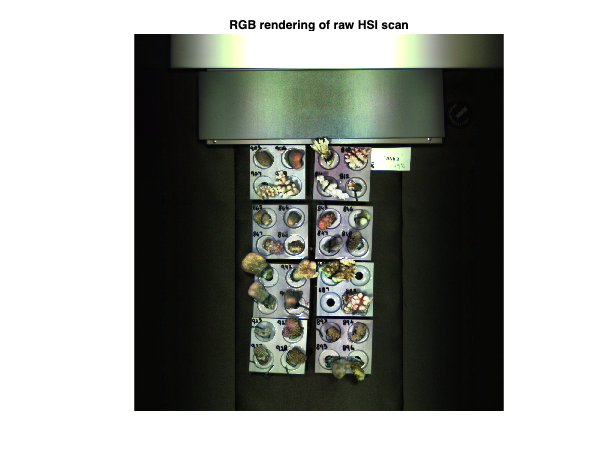

% Check HSI raw folder
content_raw_hdr = dir([folder_path_raw filesep '*.hdr']);
content_raw_bil = dir([folder_path_raw filesep '*.bil']);
% Error check if more than 1 dataset in raw folder
if ~(length(content_raw_hdr) == 1 && length(content_raw_bil) == 1)
    error('Ensure that there is only one .hdr and one .bil file in Raw Folder.')
end
% Read HSI raw
raw_hsi_filename_full_path = [folder_path_raw filesep content_raw_hdr.name];
scan_hsi_raw = hypercubeMyFun(raw_hsi_filename_full_path);
scan_rgb_raw = colorize(scan_hsi_raw,'Method','rgb','contrastStretching',true);
imshow(scan_rgb_raw)
title('RGB rendering of raw HSI scan')

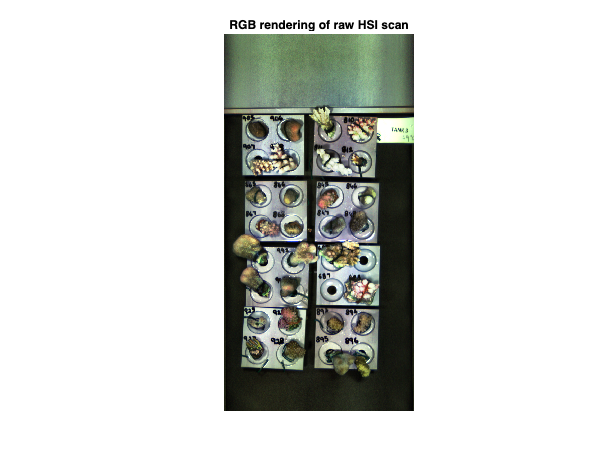

% Find white panel to exclude
scan_grey_raw = rgb2gray(scan_rgb_raw);
horizontal_brightness = sum(scan_grey_raw,2);
[horizontal_peak_value, horizontal_peak_location] = findpeaks(-diff(horizontal_brightness));
[~,horizontal_peak_value_index] = max(horizontal_peak_value);
white_panel_height_end = horizontal_peak_location(horizontal_peak_value_index);
% Find usable width
vertical_brightness = sum(scan_grey_raw,1);
[~, vertical_peak_location, ~, vertical_peak_prominences] = findpeaks((smooth(vertical_brightness)));
% Use prominences > 1 as threshold
vertical_peak_width_start_index = find(vertical_peak_prominences > 1, 1,'first');
vertical_peak_width_end_index = find(vertical_peak_prominences > 1, 1,'last');
scan_width_start = vertical_peak_location(vertical_peak_width_start_index);
scan_width_end = vertical_peak_location(vertical_peak_width_end_index);
% Crop usable region
top_buffer = 20; 
top_crop_height = white_panel_height_end+top_buffer;
tank_cropped_hsi = cropData(scan_hsi_raw,top_crop_height:scan_hsi_raw.Metadata.Height,scan_width_start:scan_width_end); 
cropped_rgb_raw = colorize(tank_cropped_hsi,'Method','rgb','contrastStretching',true);
imshow(cropped_rgb_raw)
title('RGB rendering of raw HSI scan')

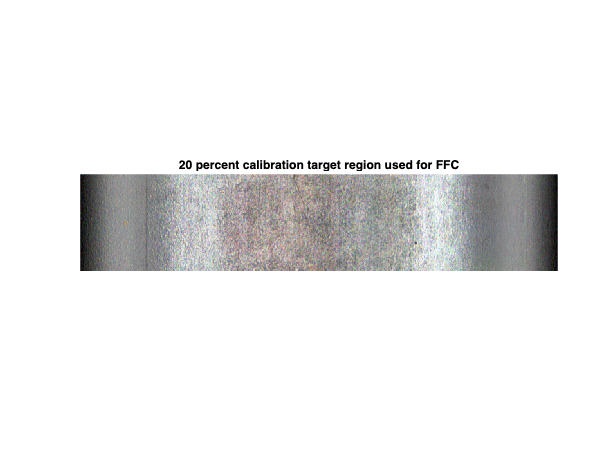

% use 50 to 200 pixel from top as grey panel for FFC
cal_target_hsi = cropData(tank_cropped_hsi,50:200,1:tank_cropped_hsi.Metadata.Width); 
cal_rgb_raw = colorize(cal_target_hsi,'Method','rgb','contrastStretching',true);
imshow(cal_rgb_raw)
title('20 percent calibration target region used for FFC')

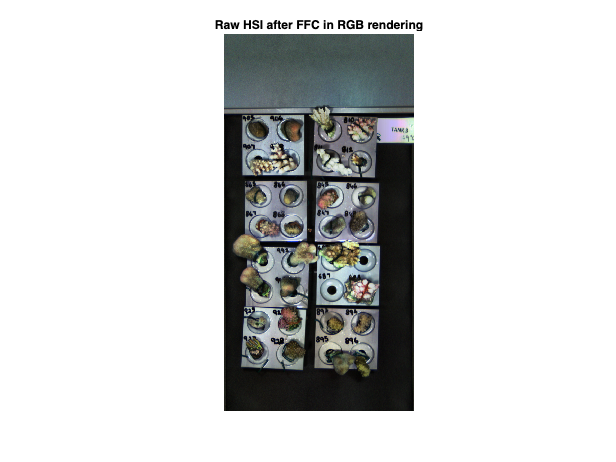

for n = 1:cal_target_hsi.Metadata.Width
    for m = 1:cal_target_hsi.Metadata.Bands
        column_data = rmoutliers(double(cal_target_hsi.DataCube(:,n,m)));
        temp_median = median(column_data);
        % Prevent Inf and Nan calculations
        if temp_median == 0 
            temp_median = 1;
        end
        ffc_profile(1,n,m) = temp_median; 
    end
end

% Apply FFC
tank_ffc_hsi = ffcHsi(tank_cropped_hsi, ffc_profile);
tank_ffc_rgb = colorize(tank_ffc_hsi,"Method","rgb","ContrastStretching",true);
% Show FFC results
imshow(tank_ffc_rgb)
title('Raw HSI after FFC in RGB rendering')

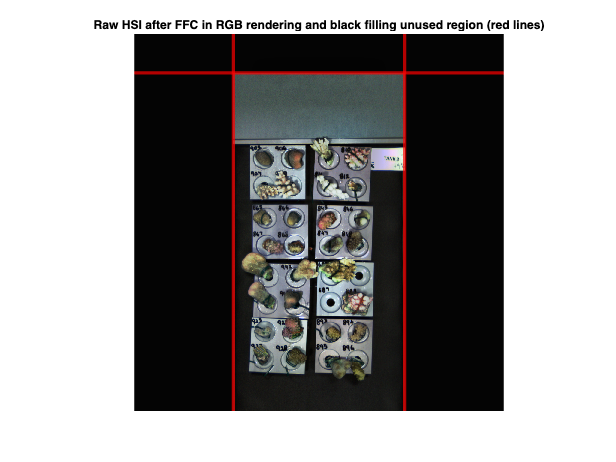

%%%% Fix for unmatched data size
% Convert back to original data cube size
scan_hsi_temp_metadata = scan_hsi_raw.Metadata;
scan_hsi_temp_metadata.DataType = "double";
scan_hsi_temp = hypercube(zeros(size(scan_hsi_raw.DataCube)),scan_hsi_raw.Wavelength,scan_hsi_temp_metadata);
tank_ffc_mod_hsi = assignData(scan_hsi_temp,top_crop_height:scan_hsi_temp.Metadata.Height,scan_width_start:scan_width_end,':',tank_ffc_hsi.DataCube);
tank_ffc_mod_rgb = colorize(tank_ffc_mod_hsi,"Method","rgb","ContrastStretching",true);
% Show FFC results
imshow(tank_ffc_mod_rgb)
xline(scan_width_start,'r','LineWidth',3)
xline(scan_width_end,'r','LineWidth',3)
yline(top_crop_height,'r','LineWidth',3)
title('Raw HSI after FFC in RGB rendering and black filling unused region (red lines)')


% Save FFC raw HSI
ffc_filename = [content_raw_hdr.name(1:end-8) '_ffc.bil.hdr'];
ffc_filename_full_path = [folder_path_ffc filesep ffc_filename];
enviwriteMyFun(tank_ffc_mod_hsi,ffc_filename_full_path);
ffc_tif_filename = [ffc_filename(1:end-7) 'tif'];
ffc_tif_filename_full_path = [folder_path_ffc filesep ffc_tif_filename];
imwrite(tank_ffc_mod_rgb,ffc_tif_filename_full_path);

## Step 2: Reflectance processing

Convert data into reflectance (normalising data) using calibration target and calibration files.

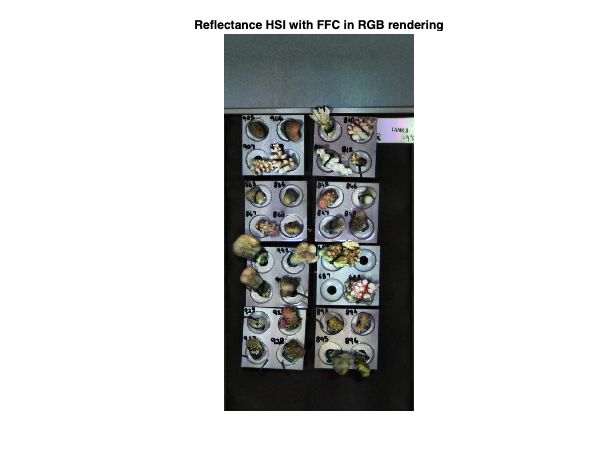

% Get cal target's raw data. 1st top 100 pixels
cal_target_datacube = tank_ffc_hsi.DataCube(1:100,:,:);
cal_target_spectrum = median(cal_target_datacube,1);

% Get reflectance
load('CalibrationTarget20Percent.mat')
cal_data = interp1(CalibrationTarget20Percent(:,1),CalibrationTarget20Percent(:,2),tank_ffc_hsi.Wavelength)'/100;

tank_ffc_rf_datacube = (tank_ffc_hsi.DataCube./cal_target_spectrum).*reshape(cal_data,1,1,length(cal_data));
tank_ffc_rf_metadata = tank_ffc_hsi.Metadata;
tank_ffc_rf_metadata.DataType = "double";
tank_ffc_rf_hsi = hypercube(tank_ffc_rf_datacube,tank_ffc_hsi.Wavelength,tank_ffc_rf_metadata);
tank_ffc_rf_rgb = colorize(tank_ffc_rf_hsi,"Method","rgb","ContrastStretching",true);

% Show reflectance image
imshow(tank_ffc_rf_rgb)
title('Reflectance HSI with FFC in RGB rendering')

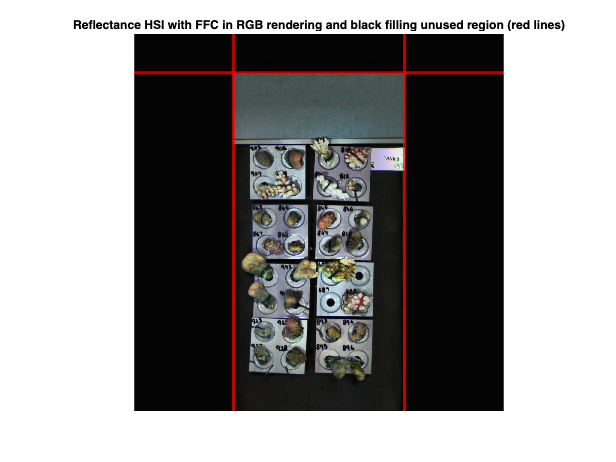

%%%% Fix for unmatched data size
% Convert back to original data cube size
scan_hsi_temp_metadata = scan_hsi_raw.Metadata;
scan_hsi_temp_metadata.DataType = "double";
scan_hsi_temp = hypercube(zeros(size(scan_hsi_raw.DataCube)),scan_hsi_raw.Wavelength,scan_hsi_temp_metadata);
tank_ffc_rf_mod_hsi = assignData(scan_hsi_temp,top_crop_height:scan_hsi_temp.Metadata.Height,scan_width_start:scan_width_end,':',tank_ffc_rf_hsi.DataCube);
tank_ffc_rf_mod_rgb = colorize(tank_ffc_rf_mod_hsi,"Method","rgb","ContrastStretching",true);
% Show FFC results
imshow(tank_ffc_mod_rgb)
xline(scan_width_start,'r','LineWidth',3)
xline(scan_width_end,'r','LineWidth',3)
yline(top_crop_height,'r','LineWidth',3)
title('Reflectance HSI with FFC in RGB rendering and black filling unused region (red lines)')

% Save FFC raw HSI
ffc_rf_filename = [content_raw_hdr.name(1:end-8) '_ffc_rf.bil.hdr'];
ffc_rf_filename_full_path = [folder_path_reflectance filesep ffc_rf_filename];
enviwriteMyFun(tank_ffc_rf_mod_hsi,ffc_rf_filename_full_path);
ffc_rf_tif_filename = [ffc_rf_filename(1:end-7) 'tif'];
ffc_rf_tif_filename_full_path = [folder_path_reflectance filesep ffc_rf_tif_filename];
imwrite(tank_ffc_rf_mod_rgb,ffc_rf_tif_filename_full_path);